# HW 10. Monte-Carlo Methods and Nonlinear Systems of Equations (Due May 11, 11:59 PM)

## Problem 1 (30 Points)

The cross-section of a wing (also known as airfoil profile) is designed to be a streamlined geometry. NACA0015 airfoil is one of these symmetric profiles. A friend of yours who is studying marine biology has found that the profile of the NACA0015 airfoil is very similar to the top-view of a trout !!

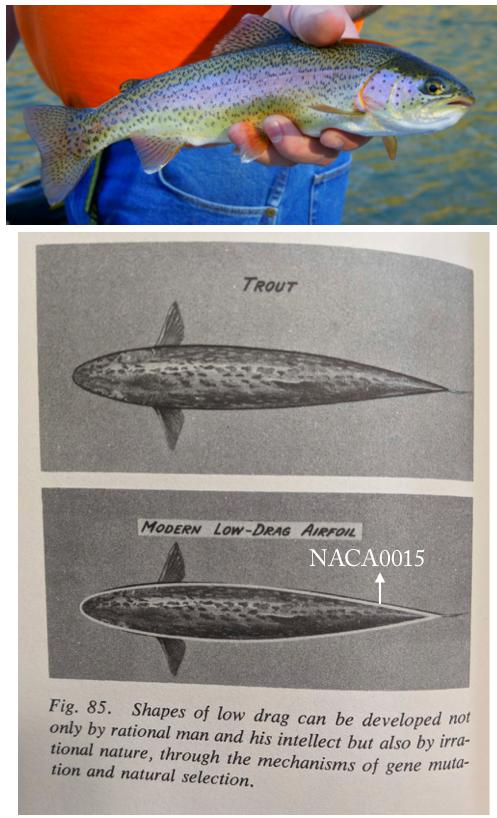

We have obtainded the digitized shapes of both of these profiles (trout=gettrout() and NACA=getNACA();). We plot both of these profiles by scaling everything with the cord length c. You can assume that c=1m for both of these profiles. 

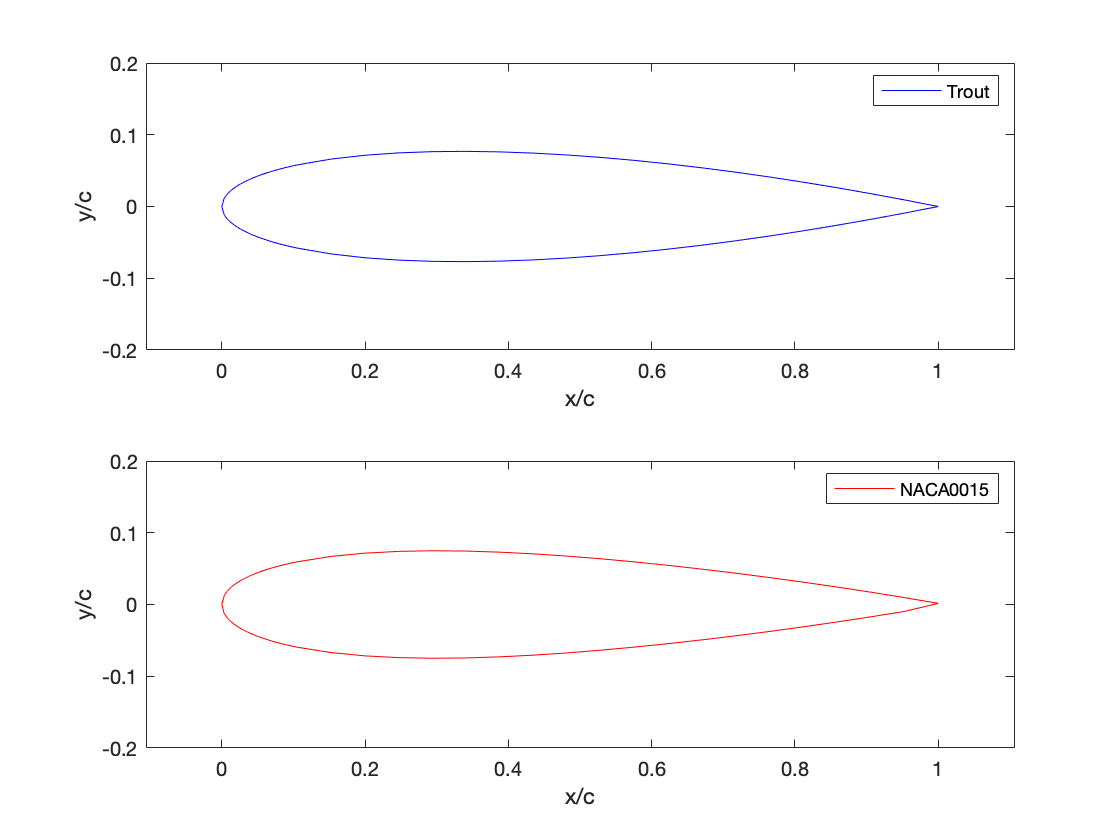

clear all
close all
trout=gettrout();% a function written at the end of the live script. You do not need to change/modify it at all.
NACA=getNACA();% a function written at the end of the live script. You do not need to change/modify it at all.
figure
subplot(2,1,1)
plot(trout(:,1),trout(:,2),'b-')
axis equal
ylim([-0.2 0.2])
xlabel('x/c')
ylabel('y/c')
legend('Trout')
subplot(2,1,2)
plot(NACA(:,1),NACA(:,2),'r-')
axis equal
ylim([-0.2 0.2])
xlabel('x/c')
ylabel('y/c')
legend('NACA0015')

In this exercise, we like to quantitatively compare these two profiles by calculating their corresponing geometrical parameters. In order to do this, we will use Monte-Carlo methods.

**(a) (5 points) ** For both profiles, select 10,000 random points inside the $[0\ 1]\times[-0.1\ 0.1]$domain. Use the Monte Carlo methods to find the area $A$, centroid position $(\bar{x}=\frac{1}{A}\int xdA \text{ and }\bar{y}=\frac{1}{A}\int ydA)$ and moments of inertia $(I_x=\int (x-\bar{x})^2dA \text{ and } I_y=\int (y-\bar{y})^2dA)$. For your estimates of the cross-sectional area $A$, please also report the corresponding 95% confidence intervals.

N=10000;
a=1;
b=0.1;
x=rand(N,1);
%place your code here:
a2 = 0;
b2 = -0.1;
y=rand(N,1)*(2*b)+b2;
A_R = (b2-b)*(a2-a);
ins_NACA = inpolygon(x,y,NACA(:,1),NACA(:,2));
area_NACA = mean(ins_NACA)*A_R

area_NACA = 0.1025

CI_NACA=[area_NACA-1.96*sqrt(var(ins_NACA*A_R)/sum(ins_NACA*A_R)) area_NACA+1.96*sqrt(var(ins_NACA*A_R)/sum(ins_NACA*A_R))]

CI_NACA =     0.0963    0.1086


ins_trout = inpolygon(x,y,trout(:,1),trout(:,2));
area_trout = mean(ins_trout)*A_R

area_trout = 0.1074

CI_trout=[area_trout-1.96*sqrt(var(ins_trout*A_R)/sum(ins_trout*A_R)) area_trout+1.96*sqrt(var(ins_trout*A_R)/sum(ins_trout*A_R))]

CI_trout =     0.1014    0.1133


xcent_NACA=mean(x(ins_NACA))

xcent_NACA = 0.4226

ycent_NACA=mean(y(ins_NACA))

ycent_NACA = -7.0187e-04

xcent_Trout=mean(x(ins_trout))

xcent_Trout = 0.4326

ycent_Trout=mean(y(ins_trout))

ycent_Trout = -8.1321e-04

Ix_NACA=area_NACA*mean((x(ins_NACA)-xcent_NACA).^2)

Ix_NACA = 0.0057

Iy_NACA=area_NACA*mean((y(ins_NACA)-ycent_NACA).^2)

Iy_NACA = 1.2908e-04

Ix_Trout=area_trout*mean((x(ins_trout)-xcent_Trout).^2)

Ix_Trout = 0.0059

Iy_Trout=area_trout*mean((y(ins_trout)-ycent_Trout).^2)

Iy_Trout = 1.4648e-04

**(b)** **(5 points)** In this part we like to see how the relative error for the Monte-Carlo estimates of the cross-sectional area depend on the height of the bounding box. We already know that the exact value for the area of the NACA0015 airfoil can be calculated by the polyarea command. Write a simpe code that estimates the cross-sectional area with N=10,000 random points that are selected in a bounding box of size $[0\ 1]\times[-b\ b]$ where $b$ sets the height of the bounding box. Vary the value of $b$ as described in the bvector=[0.05 0.055 0.06 0.065 0.07 0.08 0.1 0.25 0.5 1] and find the corresponding values of relative error for each value of $b$. Plot the relative error versus $b$. As you run the code few times which value of $b$ often corresponds to the smallest error? can you explain why?

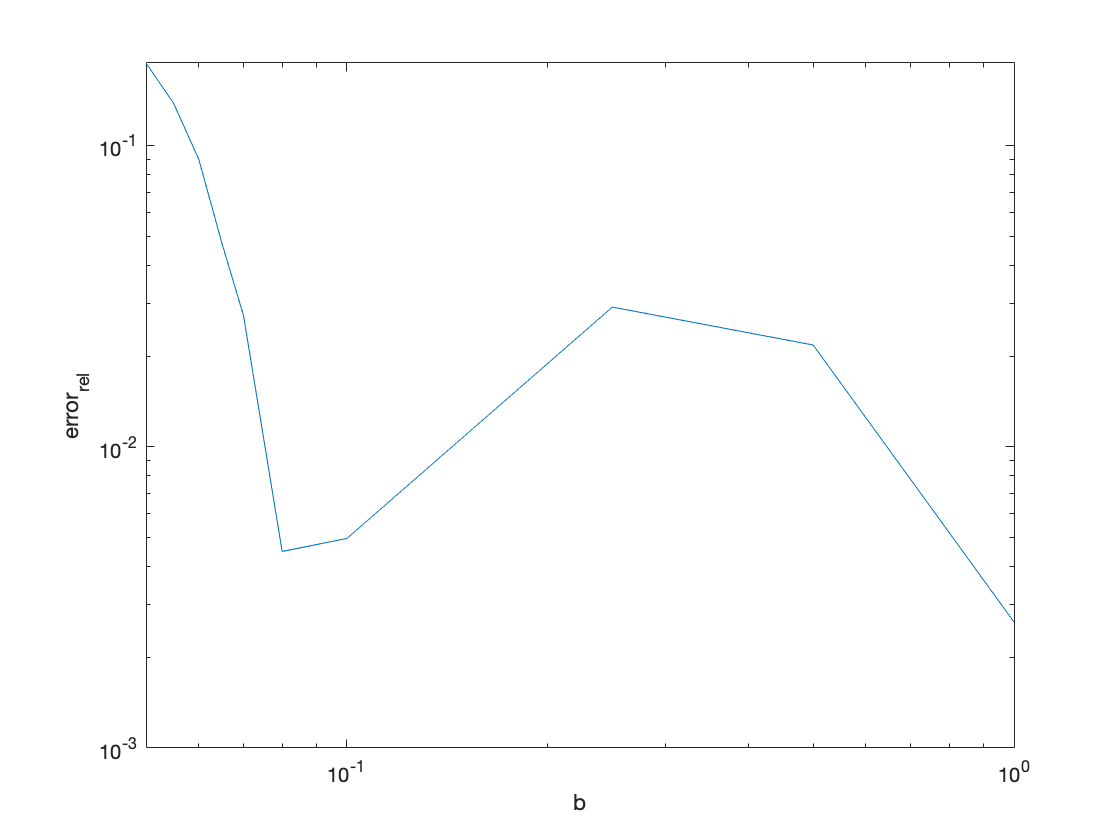

bvector=[0.05 0.055 0.06 0.065 0.07 0.08 0.1 0.25 0.5 1];
area_true=polyarea(NACA(:,1),NACA(:,2));
error_rel=[];
area_NACA = [];
for i=1:length(bvector)
    N=10000;
    a=1;
    b=bvector(i);
    x=rand(N,1);
    %place your code here:
    a2 = 0;
    b2 = -b;
    y = rand(N,1)*(2*b)+b2;
    A_R = (b2-b)*(a2-a);
    ins_NACA = inpolygon(x,y,NACA(:,1),NACA(:,2));
    area_NACA(i) = mean(ins_NACA)*A_R;
    error_rel(i)=abs(area_NACA(i)-area_true)/area_true;
end
figure
loglog(bvector,error_rel)
xlabel('b')
ylabel('error_{rel}')

% the b value with often the smallest error is around 10^-1, because the
% NACA y values range around -0.08 to 0.08 so the closer the area used to
% estimate is to the true area, the smaller the area.

**(c) (10 points)** In this part, we like to investigate about the convergence rate in the Monte-Carlo method. Vary the number of random points $N$according to the Nvector=floor(10.^(1:0.25:6)) and claculate the area of the NACA0015 airfoil. For each value of $N$, find the absolute value of error (compare your calcualated value of area with the exact result from the polyarea command). Repeat this for three times and find the average error at each value of $N$after taking the mean of the three error values (error_mean_N). Plot the claculated mean error (error_mean_N) versus $N$in a log-log plot. What is the order of convergence?

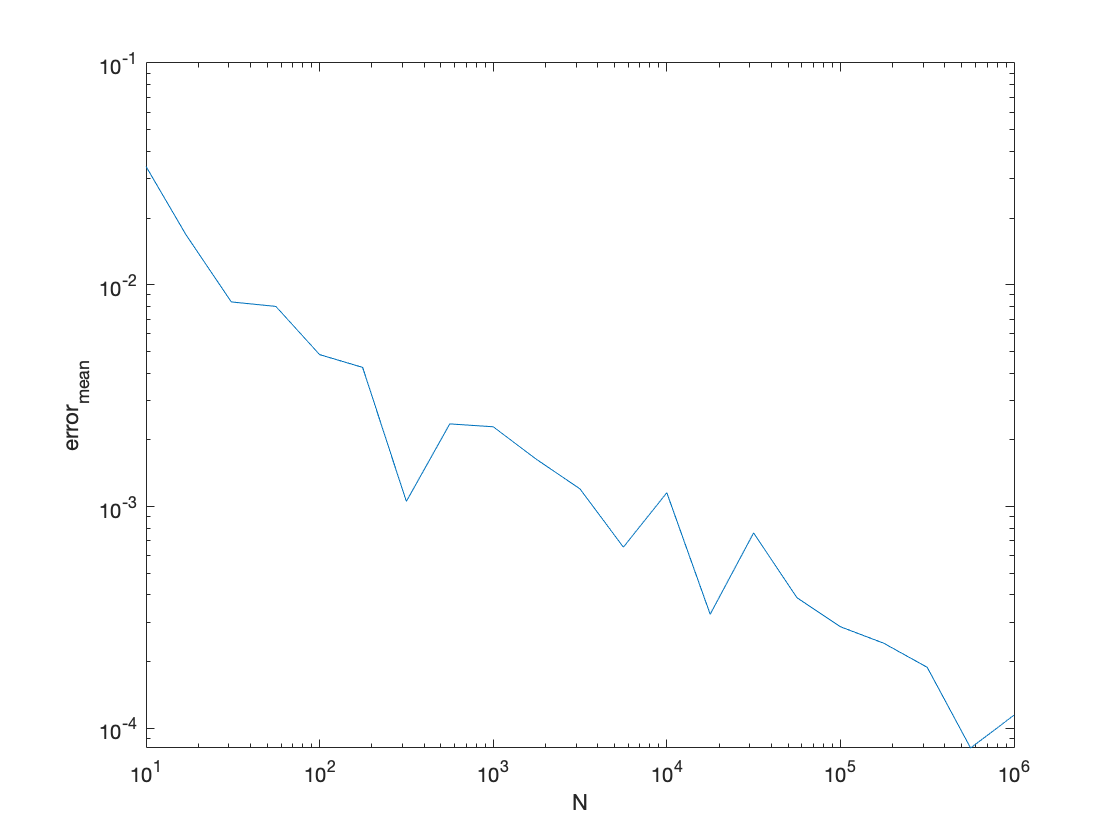

Nvector=floor(10.^(1:0.25:6));

a=1;
b=0.1;
errorN=[];
area_true=polyarea(NACA(:,1),NACA(:,2));
errorN1 = [];
for i=1:length(Nvector)
    N=Nvector(i);
    x=rand(N,1);
    a2 = 0;
    b2 = -b;
    y = rand(N,1)*(2*b)+b2;
    A_R = (b2-b)*(a2-a);
    ins_NACA = inpolygon(x,y,NACA(:,1),NACA(:,2));
    area_NACA = mean(ins_NACA)*A_R;
    errorN1(i)=abs(area_NACA-area_true);
end
errorN2 = [];
for i=1:length(Nvector)
    N=Nvector(i);
    x=rand(N,1);
    a2 = 0;
    b2 = -b;
    y = rand(N,1)*(2*b)+b2;
    A_R = (b2-b)*(a2-a);
    ins_NACA = inpolygon(x,y,NACA(:,1),NACA(:,2));
    area_NACA = mean(ins_NACA)*A_R;
    errorN2(i)=abs(area_NACA-area_true);
end
errorN3 = [];
for i=1:length(Nvector)
    N=Nvector(i);
    x=rand(N,1);
    a2 = 0;
    b2 = -b;
    y = rand(N,1)*(2*b)+b2;
    A_R = (b2-b)*(a2-a);
    ins_NACA = inpolygon(x,y,NACA(:,1),NACA(:,2));
    area_NACA = mean(ins_NACA)*A_R;
    errorN3(i)=abs(area_NACA-area_true);
end
error_mean_N=(1/3)*(errorN1+errorN2+errorN3);
figure
loglog(Nvector,error_mean_N)
xlabel('N');
ylabel('error_{mean}')

% the order of convergence is around -2, as N increases by a magnitude of 10^2
% error decreases by a magnitude of 10

 **(d)** **(10 points) **The cross-section of a wing is often made hollow by circular, rectangular, and triangular cuts that reduce the weight of the wing. A typical design is shown below: 

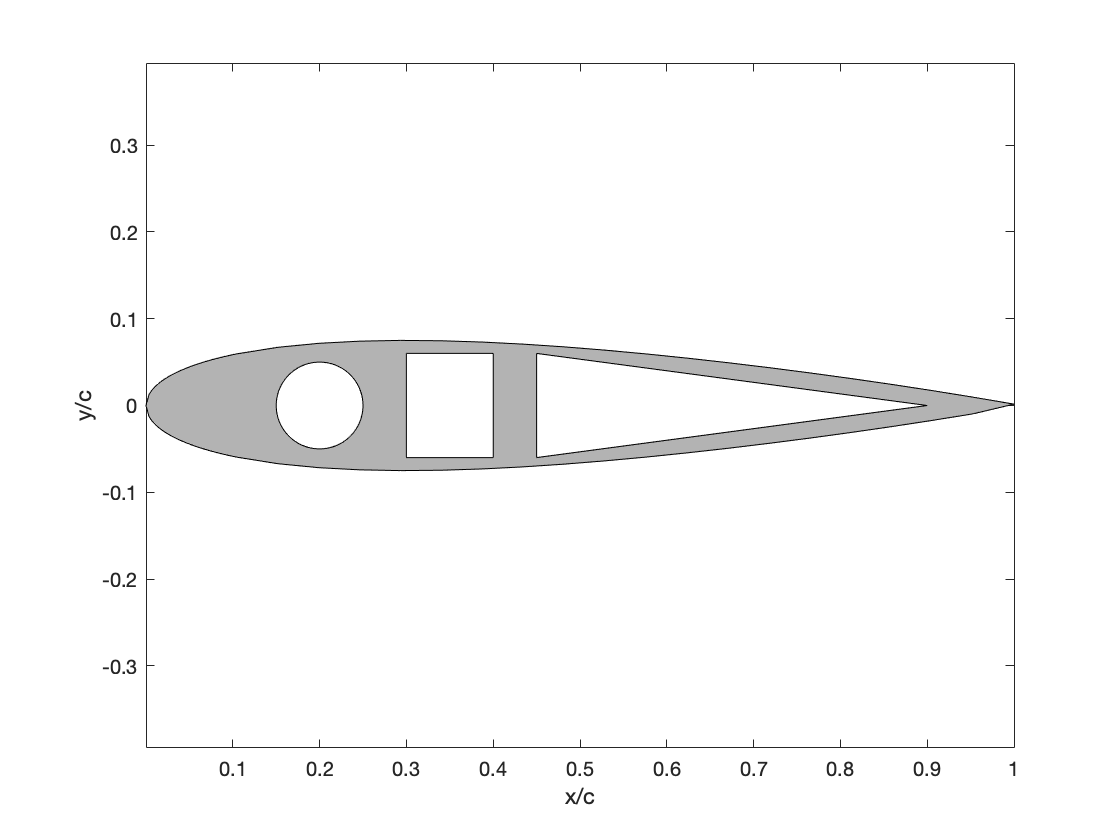

figure
plot(NACA(:,1),NACA(:,2),'r-')
hold on
axis equal
xlabel('x/c')
ylabel('y/c')
fill(NACA(:,1),NACA(:,2),[0.7,0.7,0.7])
%legend('NACA0015')
r=0.05;
x0=0.2;
y0=0;
theta=linspace(0,2*pi);
xcirc=x0+r*cos(theta);
ycirc=y0+r*sin(theta);
xsquare=[0.3 0.4 0.4 0.3];
ysquare=[0.06 0.06 -0.06 -0.06];
xtriangle=[0.45 0.9 0.45];
ytriangle=[0.06 0 -0.06];
fill(xcirc,ycirc,[1 1 1])
fill(xsquare,ysquare,[1 1 1])
fill(xtriangle,ytriangle,[1 1 1])

Write a simple code that calculates the area $A$, centroid position $(\bar{x}=\frac{1}{A}\int xdA \text{ and }\bar{y}=\frac{1}{A}\int ydA)$ and moments of inertia $(I_x=\int (x-\bar{x})^2dA \text{ and } I_y=\int (y-\bar{y})^2dA)$ for this modified design. Compared to the original (non-hollow) profile, how much reduction do you observe in the cross-sectional area? How much reduction do you observe in the value of $I_x$?

N=10000;
a=1;
b=0.1;
x=rand(N,1);
%place your code here:
a2 = 0;
b2 = -b;
y = rand(N,1)*(2*b)+b2;
A_R = (b2-b)*(a2-a);
ins_NACA_B = inpolygon(x,y,NACA(:,1),NACA(:,2))&(~inpolygon(x,y,xcirc,ycirc))&(~inpolygon(x,y,xtriangle,ytriangle))&(~inpolygon(x,y,xsquare,ysquare));
area_NACA_B = mean(ins_NACA_B)*A_R;
xcent_NACA_B= mean(x(ins_NACA_B))

xcent_NACA_B = 0.3861

ycent_NACA_B=mean(y(ins_NACA_B))

ycent_NACA_B = 6.1270e-04

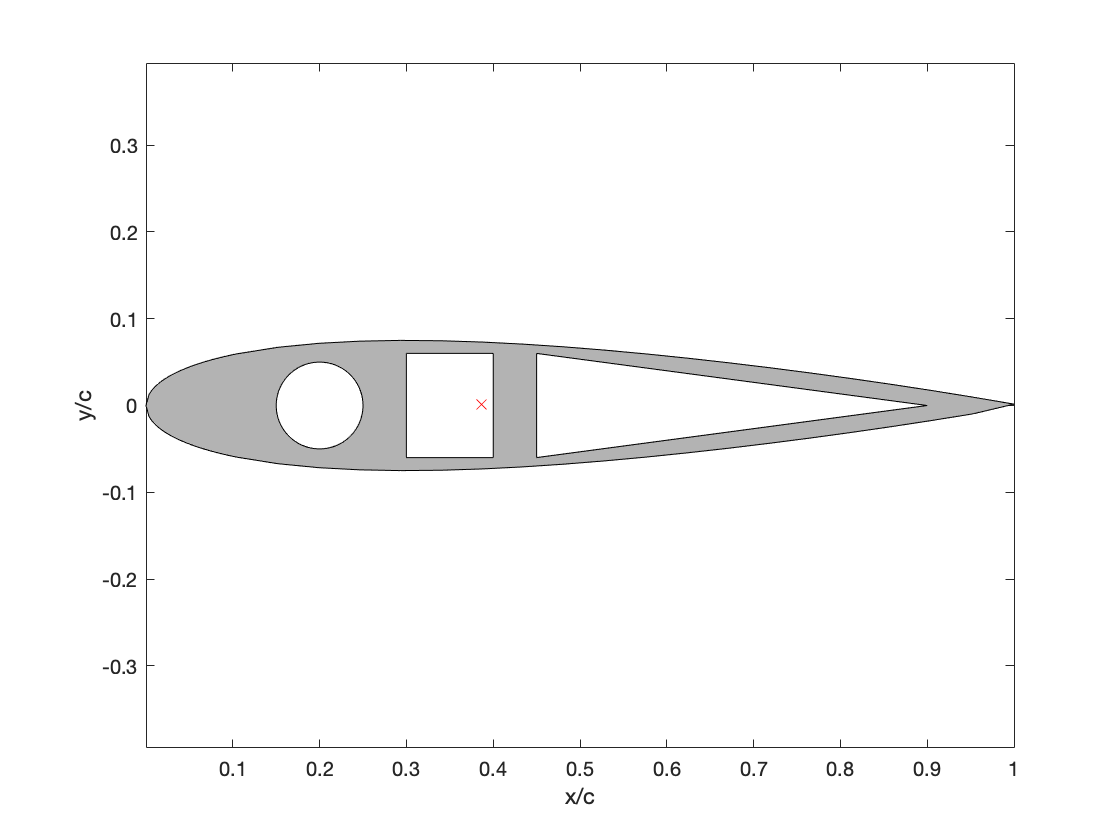

plot(xcent_NACA_B,ycent_NACA_B,'rx')

Ix_B=area_NACA_B*mean((x(ins_NACA_B)-xcent_NACA_B).^2)

Ix_B = 0.0041

Iy_B=area_NACA_B*mean((y(ins_NACA_B)-ycent_NACA_B).^2)

Iy_B = 9.4817e-05

area_NACA_B/area_NACA

ans = 0.5534

Ix_B/Ix_NACA

ans = 0.7246

## Problem 2 (20 Points)

Monte-Carlo (M-C) methods can be used for calculating integrals in different dimensions. In this problem we like to investigate the convergence rate of M-C methods in 1D, 2D and 3D integral calculations. The integrals of interest are $I_1=\int_a^b\exp(-x_1^2)dx_1$, $I_2=\int_a^b\int_a^b\exp[-(x_1^2+x_2^2)]dx_1dx_2$, and $I_3=\int_a^b\int_a^b\int_a^b\exp[-(x_1^2+x_2^2+x_3^2)]dx_1dx_2dx_3$ for 1D, 2D and 3D cases respectively. For all three cases  $a=-3$and $b=2$. Below, you can see a plot of the integrand function for the 1D case.

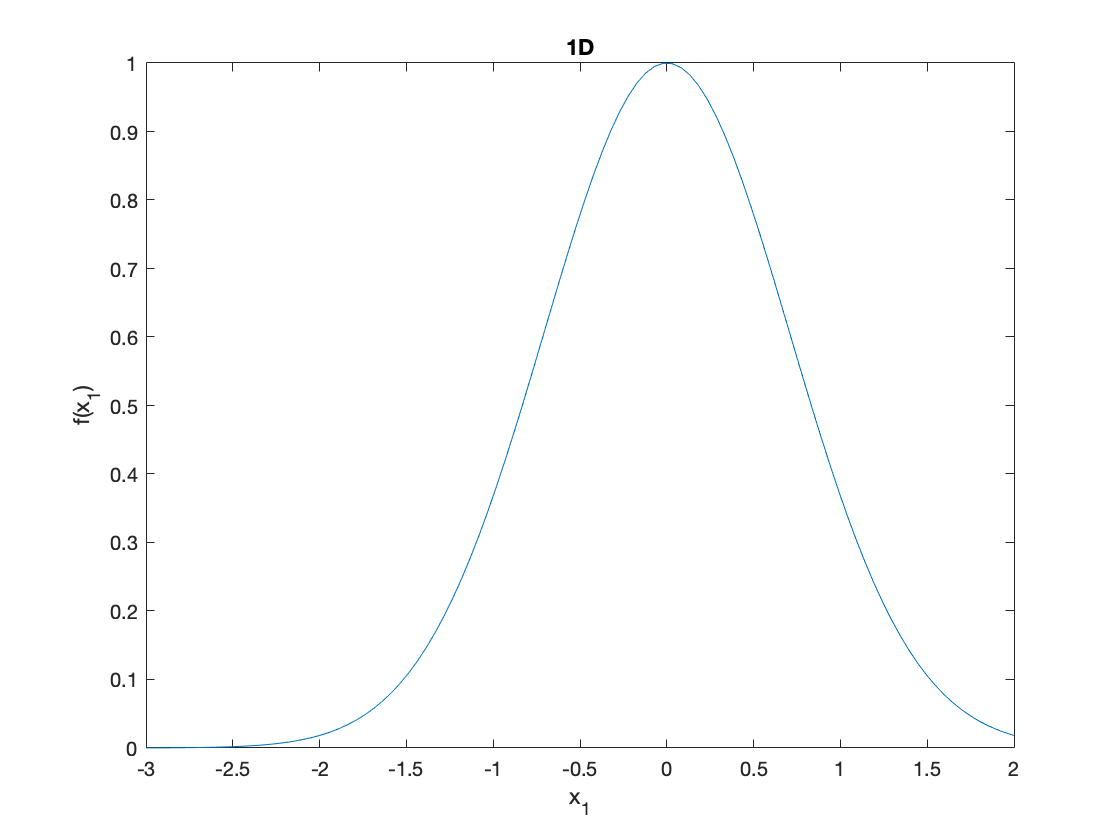

close all
clear all
x1=linspace(-3,2);
fx=exp(-x1.^2);
figure
plot(x1,fx)
xlabel('x_1');
ylabel('f(x_1)');
title('1D')

We can calculate these integrals using traditional methods such as left-point approximation. You are provided with a function named "int_leftpoint" that can calculate the integral based on left-point rectangular approximation:

[int_f_lp Np]=int_leftpoint(100,1)

int_f_lp = 1.7678

Np = 99

where N=100 is the number of descretization points for each dimension and d=1 is the dimension of the integral. Outputs are the integral value (int_f_lp) and the total number of points used in the integral calculation (Np).

The exact value of the integral can also be calculated by the following function handle:

int_f_true=@(a,b,d) (0.5*sqrt(pi)*(erf(b)-erf(a))).^d;
int_f_true(-3,2,1)

ans = 1.7683

where a and b set the limits of the integral and d is the dimension of the integral.

**(a) (4 points)** Calculate the 1D integral by the left-point method using the int_leftpoint function at different values of $N$(in the Nvector=[10 100 1000 10000 100000 1000000]) and save the corresponding values of error (error_lp_1d). For each value of $N$, find the total number of points $N_p$that is used in the left-point calculations. Write a Monte-Carlo (M_C) scheme which uses random points in the $[-3 \ 2]$ range to estimate the 1D integral. Set the number of random data-points based on the obtained $N_p$values from the left-point calculations. Plot the measured errors verus $N_p$(using loglog command) for both left-point and M-C methods. 

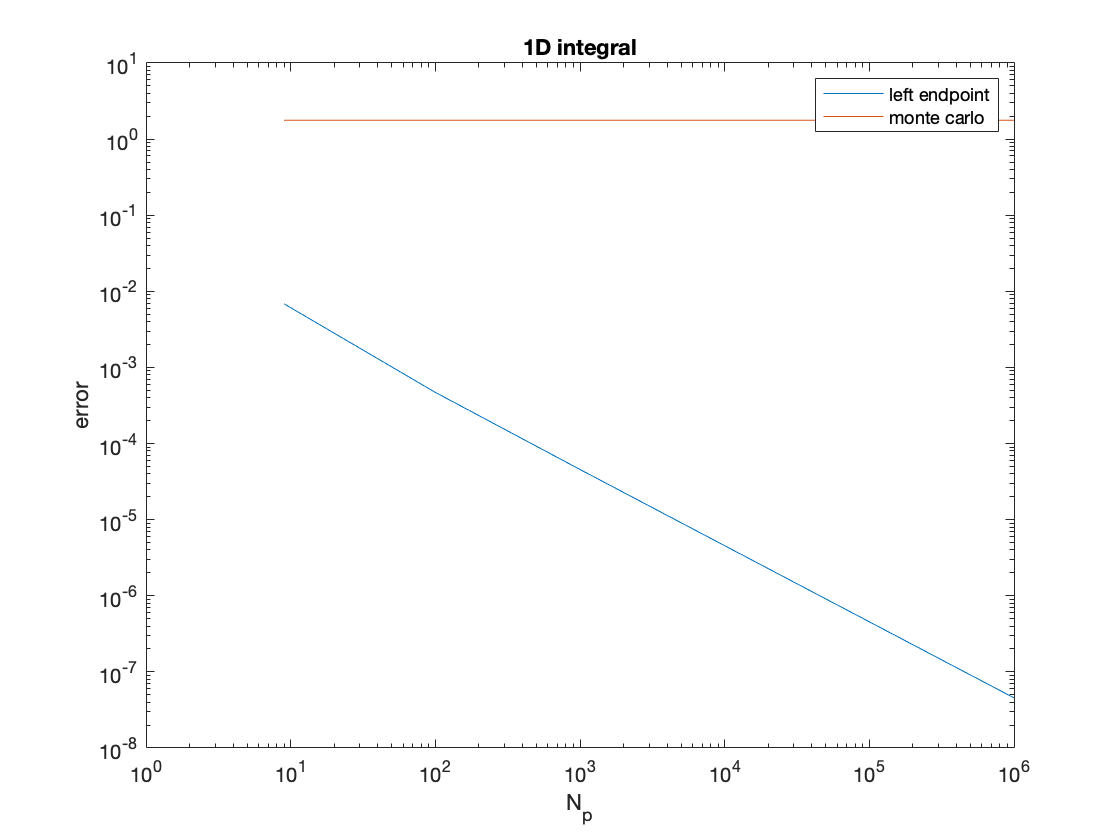

% Place your code here:
Nvector=[10 100 1000 10000 100000 1000000];
truevalue=int_f_true(-3,2,1);
error_lp_1d=[];
Npvector_1d = [];
for i=1:length(Nvector)
    N=Nvector(i);
    [int_f_lp Np]=int_leftpoint(N,1);
    Npvector_1d(i) = Np;
    error_lp_1d(i)=abs(int_f_lp-truevalue);
end
loglog(Npvector_1d,error_lp_1d)
hold on
error_MC_1d = [];
a = -3;
b = 2;
a2 = 0;
b2 = 1;
A_R = (b2-a2)*(b-a);
for i=1:length(Npvector_1d)
    N=Npvector_1d(i);
    x = rand(N,1)*(b-a)+a;
    y = rand(N,1);
    ins_1d = zeros(1,length(x));
    for j = 1:length(x)
        if y(j)<-x(j)^2
            ins_1d(j) = 1;
        end
    end
    ins_1d = logical(ins_1d);
    int_f_MC = mean(ins_1d)*A_R;
    error_MC_1d(i)=abs(int_f_MC-truevalue);
end
loglog(Npvector_1d,error_MC_1d)
xlabel('N_p');
ylabel('error');
title('1D integral')
legend("left endpoint","monte carlo")

**(b)** **(1 Point)** Can you comment on the slopes that you observe for the convergence rate of the two methods?

% Place your comments here:
% the monte carlo method has convergence rate of 0
% the left endpoint method has convergence rate of -1; as Np increases
% error decreases by the same magnitude

We can repeat the same process for the 2D integral. The 2D integral corresponds to the volume under the following surface:

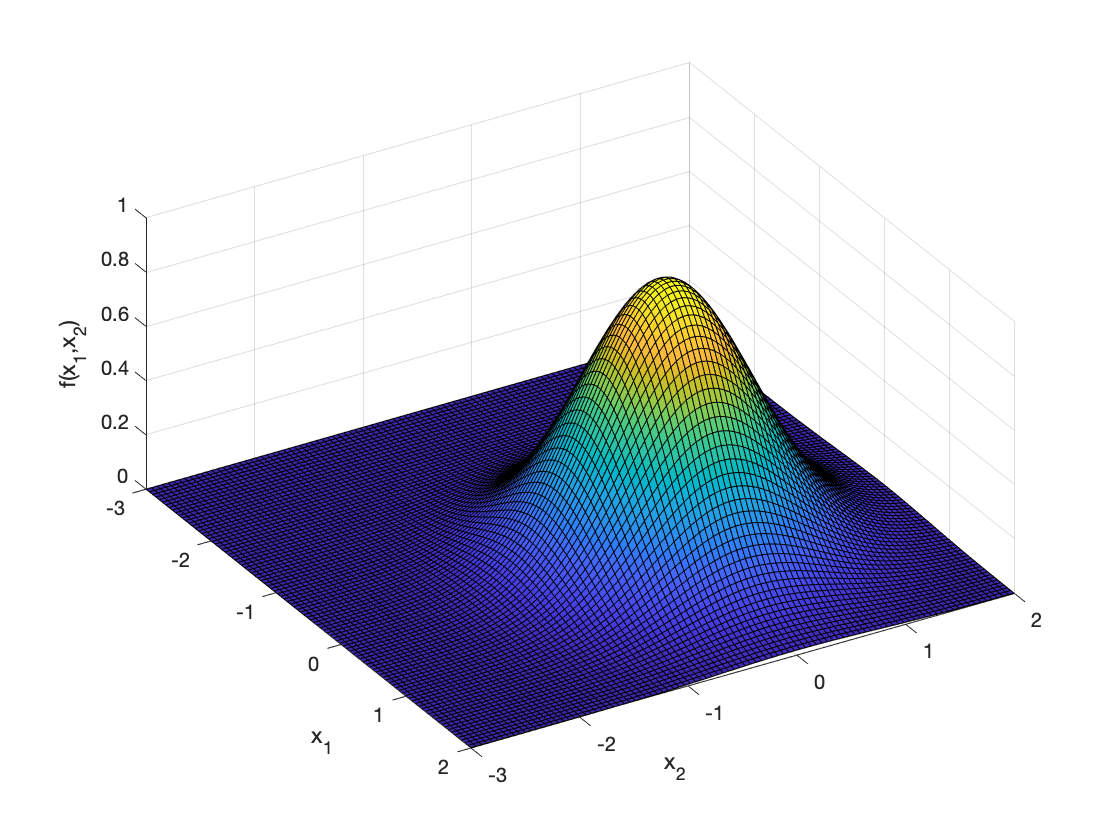

x1=linspace(-3,2);
x2=linspace(-3,2);
[X1 X2]=meshgrid(x1,x2);
F=exp(-(X1.^2+X2.^2));
figure
surf(X1,X2,F)
view([59.100 48.026])
xlabel('x_1');
ylabel('x_2');
zlabel('f(x_1,x_2)')

**(c)** **(4 points)** Calculate the 2D integral by the left-point method using the int_leftpoint function at different values of $N$(in the Nvector=[10 30 100 200 500 1000]) and save the corresponding values of error (error_lp_2d). For each value of $N$, find the total number of points $N_p$that is used in the left-point calculations. Write a Monte-Carlo scheme which uses random points in the $[-3 \ 2]\times[-3 \ 2]$ domain to estimate the 2D integral. Change the number of random data points based on the values of $N_p$that were used in the left-point calculations. Plot the measured errors verus $N_p$(using loglog command) for both left-point and M-C methods. 

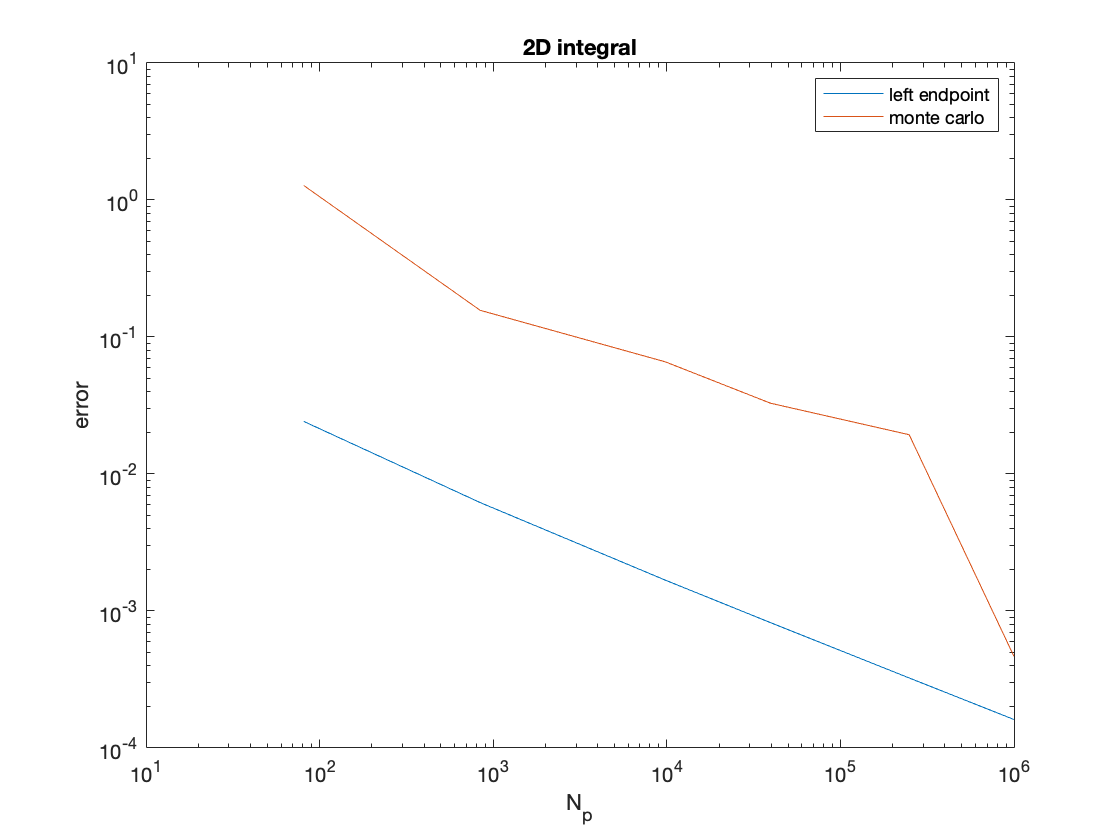

% Place your code here:
Nvector=[10 30 100 200 500 1000];

truevalue=int_f_true(-3,2,2);
error_lp_2d=[];
Npvector_2d = [];
for i=1:length(Nvector)
    N=Nvector(i);
    [int_f_lp Np]=int_leftpoint(N,2);
    Npvector_2d(i) = Np;
    error_lp_2d(i)=abs(int_f_lp-truevalue);
end
a = -3;
b = 2;
a2 = -3;
b2 = 2;
c = min(min(F));
c2 = max(max(F));
V_R = (b-a)*(b2-a2)*(c2-c);
error_MC_2d = [];
for i=1:length(Npvector_2d)
    N=Npvector_2d(i);
    x = rand(N,1)*(b-a)+a;
    y = rand(N,1)*(b2-a2)+a2;
    z = rand(N,1)*(c2-c)+c;
    ins_2d = zeros(1,length(x));
    for j = 1:length(x)
        if z(j)<exp(-(x(j).^2+y(j).^2))
            ins_2d(j) = 1;
        end
    end
    ins_2d = logical(ins_2d);
    int_f_MC = mean(ins_2d)*V_R;
    error_MC_2d(i)=abs(int_f_MC-truevalue);
end
figure
loglog(Npvector_2d,error_lp_2d)
hold on
loglog(Npvector_2d,error_MC_2d)

xlabel('N_p');
ylabel('error');
title('2D integral')
legend("left endpoint","monte carlo")

**(d) (1 point)** Can you comment on the slopes that you observe for the convergence rate of the two methods?

% Place your comments here
% the left endpoint method's rate of convergence is -2
% the monte carlo method's rate of convergence is also around -2

**(e) (4 points)** Calculate the 3D integral by the left-point method using the int_leftpoint function at different values of $N$(in the Nvector=[3 7 10 20 30 100]) and save the corresponding values of error (error_lp_3d). For each value of $N$, find the total number of points $N_p$that is used in the left-point calculations. Write a Monte-Carlo scheme which uses random points in the $[-3 \ 2]\times[-3 \ 2]\times[-3 \ 2]$ domain to estimate the 3D integral. Set the number of random data-points based on the values of $N_p$that were used in the left-point calculationsthe. Plot the measured errors verus $N_p$(using loglog command) for both left-point and M-C methods. 

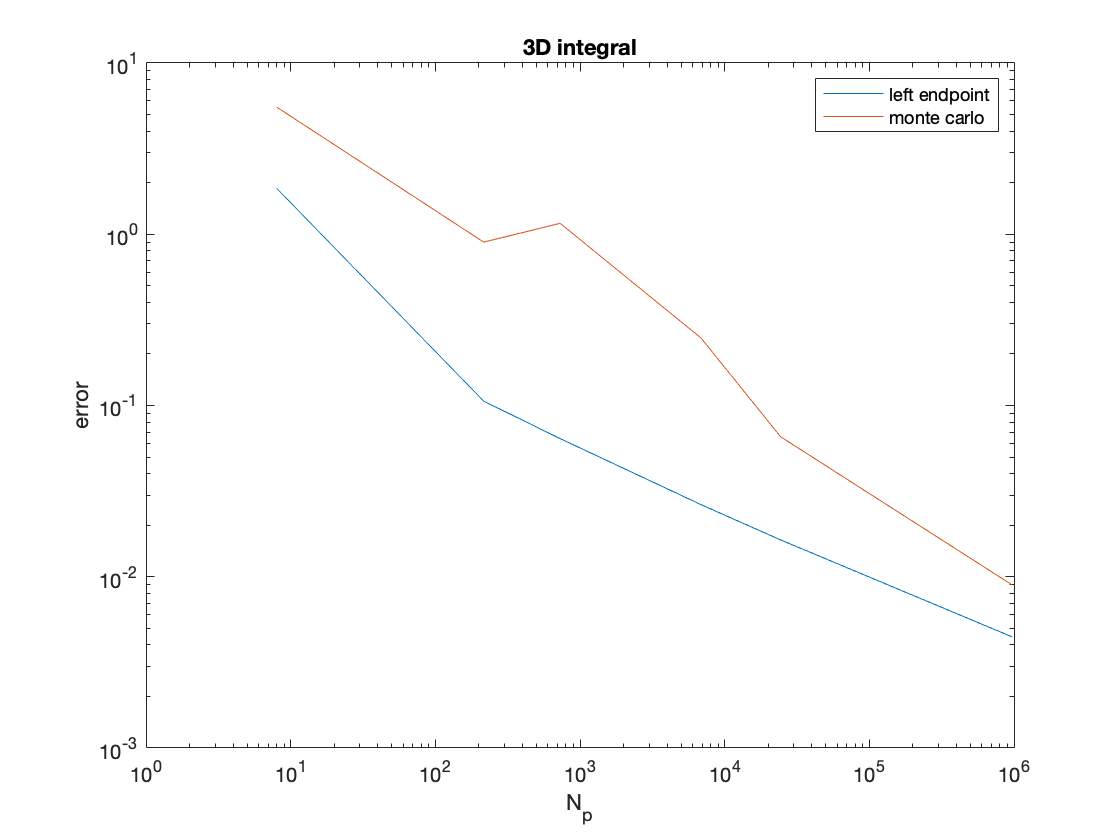

% Place your code here:
Nvector=[3 7 10 20 30 100];
truevalue=int_f_true(-3,2,3);
error_lp_3d=[];
Npvector_3d=[];
for i=1:length(Nvector)
    N=Nvector(i);
    [int_f_lp Np]=int_leftpoint(N,3);
    Npvector_3d(i) = Np;
    error_lp_3d(i)=abs(int_f_lp-truevalue);
end
error_MC_3d=[];
x1=[];
x2=[];
x3=[];
a = -3;
b = 2;
M_R = (b-a)^3;
for i=1:length(Npvector_3d)
    N=Npvector_3d(i);
    x1 = rand(N,1)*(b-a)+a;
    x2 = rand(N,1)*(b-a)+a;
    x3 = rand(N,1)*(b-a)+a;
    y = rand(N,1);
    ins_3d = zeros(1,length(x1));
    for j = 1:length(x1)
        if y(j)<exp(-(x1(j).^2+x2(j).^2+x3(j).^2))
            ins_3d(j) = 1;
        end
    end
    ins_3d = logical(ins_3d);
    int_f_MC = mean(ins_3d)*M_R;
    error_MC_3d(i)=abs(int_f_MC-truevalue);
end
figure
loglog(Npvector_3d,error_lp_3d)
hold on
loglog(Npvector_3d,error_MC_3d)
xlabel('N_p');
ylabel('error');
title('3D integral')
legend("left endpoint","monte carlo")

**(f) (1 point)** Can you comment on the slopes that you observe for the convergence rate of these two methods?

% Place your comments here:


**(g) (5 points)** Based on your observations from parts (a), (b) and (c) which method would you prefer to use for a 4D or 5D integral ?

% place your comments here:


## Problem 3 Random Walkers (30 Points)

Pictures below show the recorded tracking that was done for microscopic tracing particles that were placed in water under a microscope. As reported by Perrin (French physicist 1870-1942), the trajectory of any given particle looks like a "random" walk.

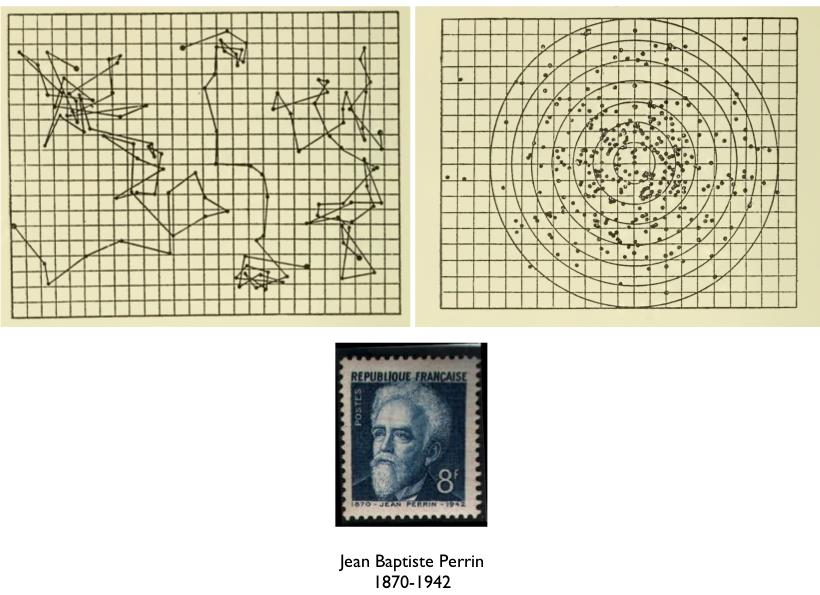

**(a) (5 points)** In many physical phenomena molecules transform heat and momentum by diffusion which is a process based on random collisions between molecules. These processes can be understood by a simple idea, which is known as the "random walk" model. First we try to numarically simulate the 2D random walk for a single particle. Assume that at time $t=0$ the particle is placed at $x_0=0,y_0=0$. You are given the information that for a given time step $\delta t=0.1$ the particle can take a displacement $(\delta x, \delta y)$where $\delta_x$and $\delta_y$are both independent random numbers that are uniformly distributed in the $[-1 \ 1]$ range. Write a simple code that finds and plots the random trajectory of the particle in the $0\leq t\leq 10$range (t=0:deltat:10). Does your plot look like Perrin's image (top-left in the picture above) ?

% place your code here:
%close all
%clear all
x0=0;
y0=0;

deltaxy=1;
deltat=0.1;
t=0:deltat:10;
n=length(t);
x=zeros(1,n);
y=zeros(1,n);

%...
for j=2:n

    %...

end

% figure
% plot(x,y,'b.-')
% xlabel('x')
% ylabel('y')

**(b)** **(5 points) **Random walk of many particles (Monte-Carlo simulation): 

Now we can study the collective behavior of many particles that are going through a random walk process. Assume that $n_p=50000$ particles are uniformly distributed in the $[-0.2\ 0.2]\times[-0.2\ 0.2]$domain at $t=0$. You are given the information that for a given time step $\delta t=0.1$each particle takes a displacement $(\delta x, \delta y)$where $\delta_x$and $\delta_y$are both independent random numbers that are uniformly distributed in the $[-1 \ 1]$ range. Write a simple code that finds the random trajectory of all the particles in the $0\leq t\leq 10$range (t=0:deltat:10 with length $n$). Save the x-coordinate of all the particles (throughout different potins in time) in the x matrix (with size $n_p\times n$) and the y-coordinate of all the particles (throughout different potins in time) in the y matrix (with size $n_p\times n$). Similarly record and save the radial position of all the particles (throughout different potins in time) in the *r* matrix (with size $n_p\times n$). Plot the 2D histogram for the final position of particles at $t=t(end)$ (hint: histogram2 is a useful command here).

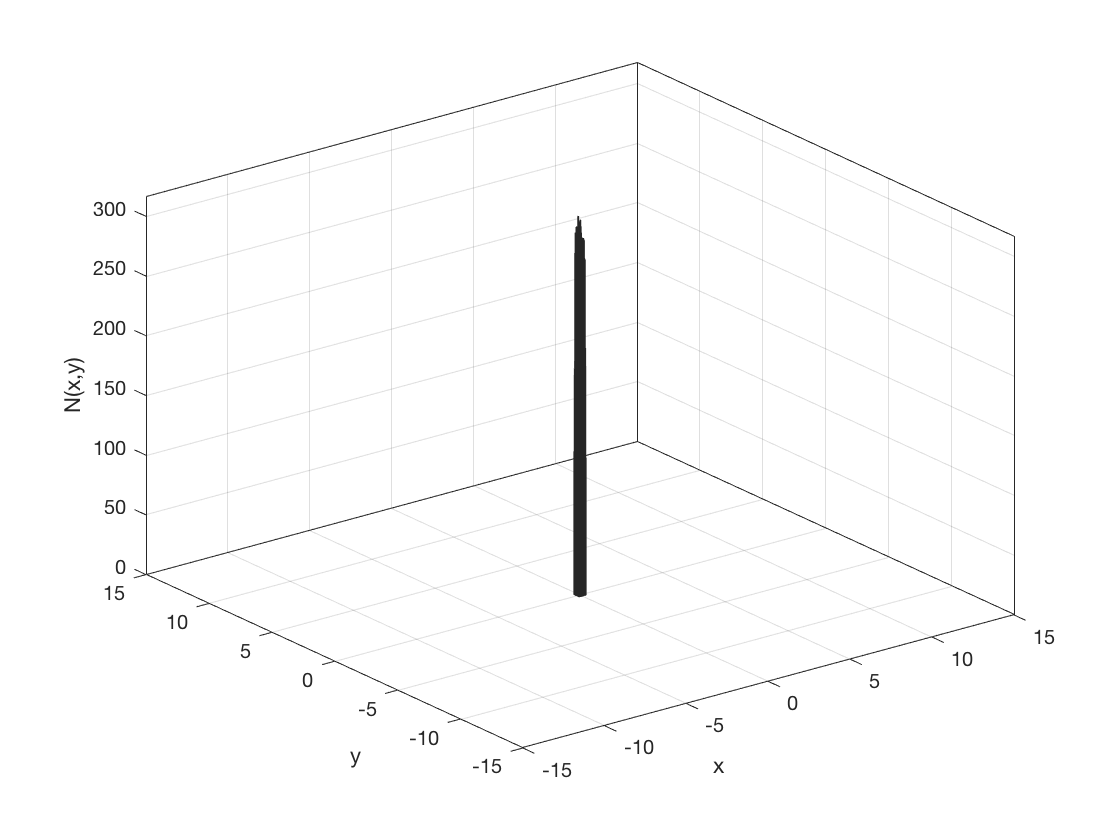

np=50000;
x0=-0.2+0.4*rand(np,1);
y0=-0.2+0.4*rand(np,1);
figure
histogram2(x0,y0)
xlim([-15 15])
ylim([-15 15])
xlabel('x')
ylabel('y')
zlabel('N(x,y)')

% place your code here:
deltat=0.2;
t=0:deltat:10;
n=length(t);
x=zeros(np,n);
y=zeros(np,n);
r=zeros(np,n);

%....

for j=2:n
%...
end

% figure
% histogram2...
% xlabel('x')
% ylabel('y')
% zlabel('N(x,y)')

**(c) (5 points)** In 3 seperate figures, plot the 1D histogram for the final x-coordinate of all the particles at $t=t(end)$, plot the 1D histogram for the final y-coordinate of all the particles at $t=t(end)$, and plot the 1D histogram for the final radial position *r* of all the particles at $t=t(end)$. Which histograms look similar to the Normal distribution? Which ones are different ? can you comment why they look different ?

% place your code here:

%figure
%histogram ...
% xlabel('x')
% ylabel('N(x)')
%place your comments here: 



%figure
%histogram ...
%xlabel('y')
%ylabel('N(y)')
%place your comments here: 



%figure
%histogram
%xlabel('r')
%ylabel('N(r)')
%place your comments here: 

**(d) (5 points)** From the last histogram for the radial position data at $t(end)$, you have noticed that the histogram has a maximum value at $r_{max}(t=t_{end})$. Write a code that will find the value of $r_{max}(t)$at each timestep by investigating the corresponsing histogram of the radial positions at a given time $t$ (keep the number of bins equal to 40 for every histogram). 

Hint: [counts centers]=hist(r(:,j),40); is a helpful line that gives you the corresponding counts and centers of the hitogram data for all 40 bins at time $t=t(j)$.

Plot the evolution of $r_{max}(t)$with time and fit the data with the $r_{max}(t)=c_0\sqrt{Dt}$ formula where $c_0$ is a fitting coefficiant and $D$ is the diffusion constant that is set by a combination of the spatial and temporal steps $D=(deltaxy)^2/deltat$. Find the value of $c_0$ from the fit. 

(Hint: you can easily use linear regression to find the fitting parameter for this fit. Take the square of the fitting formula !!).  

Plot the fit and compare it with the data.

% place your code here:
r_max=[];
for j=1:n
    %[counts centers]=hist(r(:,j),40);
   
    %r_max(j)=...;
end
%figure
%plot(t,r_max)

%D=(deltaxy^2/deltat);
%...
%hold on
%plot(t,r_max_fit)

**(e) (5 points)** Construct a probablity density function (PDF) from the recorded histogram for the radial position of particles at $t(end)$. Plot the resulting PDF and compare it with the follwoing distribution:

Rayleigh Distribution $p(r)=\frac{r}{\sigma^2}\exp(-\frac{r^2}{2\sigma^2})$ where $\sigma=r_{max}(t_{end})$.

%figure
%histogram(r(:,n))
%xlabel('r')
%ylabel('N(r)')

% place your code here:

%...
%pdf=
%figure
%hold on
%plot(centers,pdf,'ko')

%rplot=linspace(0,max(centers));
%pr=...
%plot(rplot,pr)
%legend('pdf from histogram','Rayleigh Distribution')
%xlabel('r');
%ylabel('p(r)')

**(f) (5 points)** We can now use this Monte-Carlo simulation to model diffusive processes such as heat transfer through conduction (you have seen or will see this topic in 2.005). Imagine "heated" molecules are concentrated inside the MIT logo as shown here:

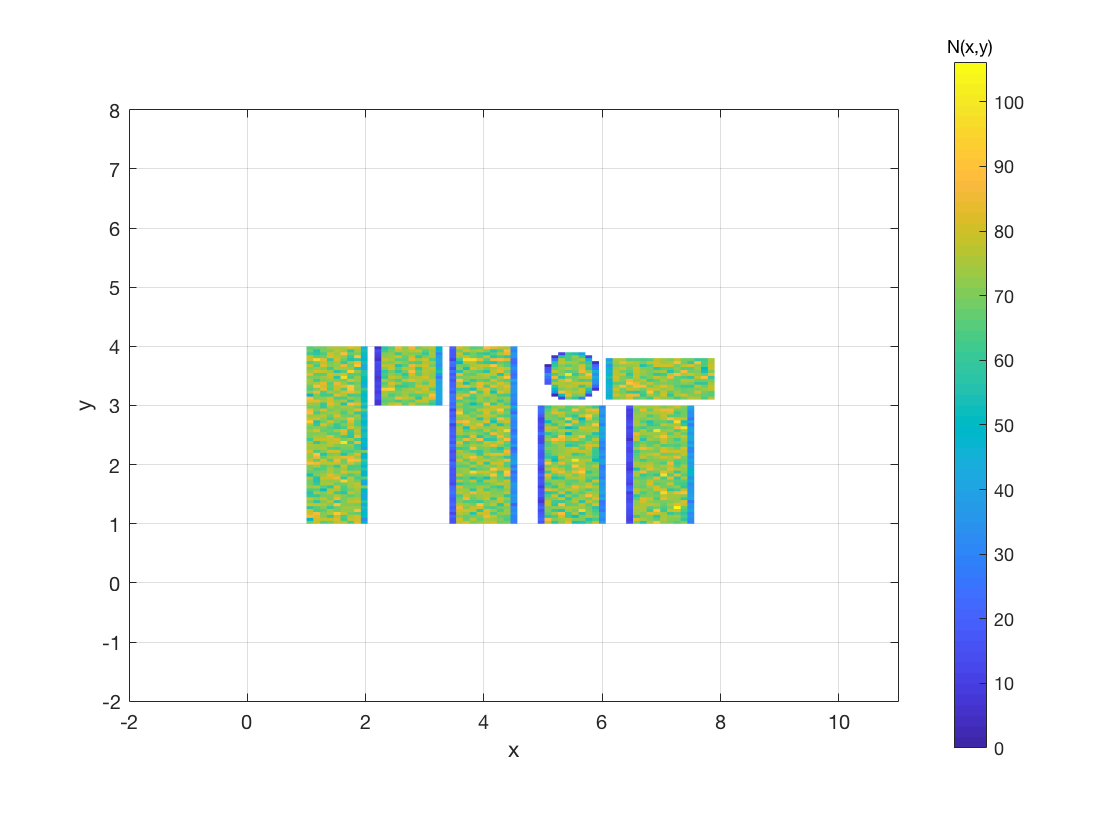

% this section provides the plot for you and you do not need to modify it.
M1=[1 1;1 4;2 4;2 1;1 1];
M2=[2.25 3;2.25 4;3.25 4;3.25 3;2.25 3];
M3=[3.5 1;3.5 4;4.5 4;4.5 1;3.5 1];
I1=[5 1;5 3;6 3;6 1;5 1];
theta=linspace(0,2*pi);
r0=0.4;
I2=[5.5+r0*cos(theta') 3.5+r0*sin(theta')];
T1=[6.5 1;6.5 3;7.5 3;7.5 1;6.5 1];
T2=[6.1 3.1;6.1 3.8;7.9 3.8;7.9 3.1;6.1 3.1];
N=500000;
xp=8*rand(N,1);
yp=5*rand(N,1);
ins=inpolygon(xp,yp,M1(:,1),M1(:,2)) | inpolygon(xp,yp,M2(:,1),M2(:,2)) | inpolygon(xp,yp,M3(:,1),M3(:,2))...
   | inpolygon(xp,yp,I1(:,1),I1(:,2)) | inpolygon(xp,yp,I2(:,1),I2(:,2))...
   | inpolygon(xp,yp,T1(:,1),T1(:,2)) | inpolygon(xp,yp,T2(:,1),T2(:,2));
xMIT=xp(ins);% These are the x-coordinates of all the particles at t=0 
yMIT=yp(ins);% These are the y-coordinates of all the particles at t=0
figure
histogram2(xMIT,yMIT,60,'FaceColor','flat','ShowEmptyBins','off')
colorbar
hcb=colorbar;
title(hcb,'N(x,y)')

axis equal
view([0.3 90.0])
xlim([-2 11])
ylim([-2 8])
xlabel('x')
ylabel('y')

Given that deltat=0.1, Find the value of deltaxy which gaurantees a diffusion constant $D=0.1\:\text{m}^2/\text{s}$. Run your code from part b and record the position of all the particles at different times in x and y matrices.

Using the subplot command, plot the 2D histograms for the position of all the particles in 6 subplots for 6 different times ($t(j=1)$,$t(j=10)$,$t(j=50)$,$t(j=100)$,$t(j=300)$and $t(j=500)$). 

deltat=0.1;
deltaxy=0.1;
np=sum(ins);
t=0:deltat:50;
n=length(t);
x=zeros(np,n);
y=zeros(np,n);
r=zeros(np,n);
x(:,1)=xMIT;
y(:,1)=yMIT;

for j=2:n
%...
end

% place your code here:
figure
subplot(3,2,1)
%histogram2(...,...,60,'FaceColor','flat','ShowEmptyBins','off')
%colorbar
%axis equal
view([0.3 90.0])
xlim([-2 11])
ylim([-2 8])

subplot(3,2,2)
%histogram2(...,...,60,'FaceColor','flat','ShowEmptyBins','off')
%colorbar
%axis equal
view([0.3 90.0])
xlim([-2 11])
ylim([-2 8])

subplot(3,2,3)
%histogram2(...,...,60,'FaceColor','flat','ShowEmptyBins','off')
%colorbar
%axis equal
view([0.3 90.0])
xlim([-2 11])
ylim([-2 8])

subplot(3,2,4)
%histogram2(...,...,60,'FaceColor','flat','ShowEmptyBins','off')
%colorbar
%axis equal
view([0.3 90.0])
xlim([-2 11])
ylim([-2 8])

subplot(3,2,5)
%histogram2(...,...,60,'FaceColor','flat','ShowEmptyBins','off')
%colorbar
%axis equal
view([0.3 90.0])
xlim([-2 11])
ylim([-2 8])

subplot(3,2,6)
%histogram2(...,...,60,'FaceColor','flat','ShowEmptyBins','off')
%colorbar
%axis equal
view([0.3 90.0])
xlim([-2 11])
ylim([-2 8])

## Problem 4 Nonlinear Systems (20 Points)

In this exercise, we like to find the axial location where a beam has zero deflection.  A loading condition was given by Shigley as: 

https://www.philadelphia.edu.jo/academics/mgogazeh/uploads/DESIGN%201%20CH4.pdf

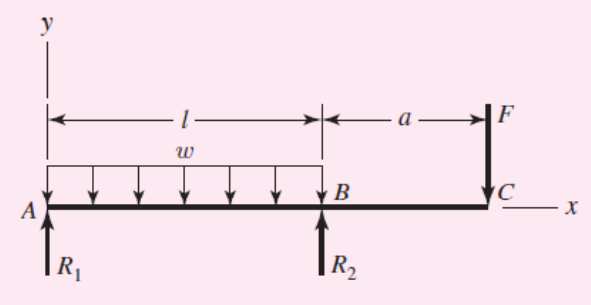

And the resulting deflection in the overhanging part of the beam is:  

Let's say that $w=250$, $l=2$, $a=1$, $\textrm{EI}={10}^4$, $F=100$.  In that case, the deflection is:

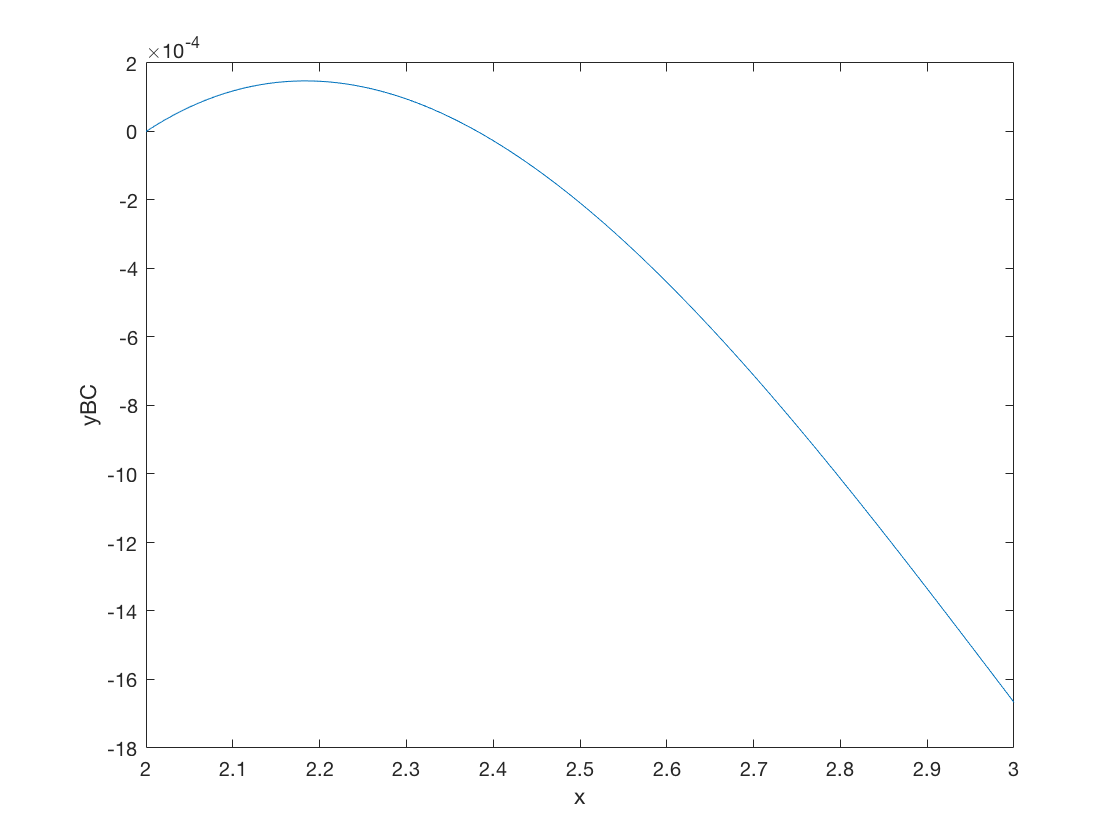

yBC=@(x) (250*2^3/(24*10000))*(x-2)+(100*(x-2)/(6*10000)).*(((x-2).^2)-1*(3*x-2));
xp=2:0.01:3;
plot(xp,yBC(xp))
xlabel('x')
ylabel('yBC')

**(a) (5 points)** Find a root for this equation within the interval 2<x<3 with the fzero command and save it in xroot.

% place your code here:
%...
%xroot=fzero

**(b) (5 points)** Write a simple code that finds a root between 2.1 and 2.9 for this equation by applying the bisection method. In each iteration record the distance between your guess and the exact solution in error_BS (you can assume that the exact solution is xroot that you already found in a).

% Place your code here:

g2=2.1;
g3=2.9;

%...
 %while (g3-g2)>10^-6
     % ....
     %error_BS(i)=abs(xroot-new_guess);
 %end
 % ts_bisect3=mean([g2 g3])

**(c)** **(5 points)** Write a simple code that finds a root for this equation by applying the Newton method. Start from inital guess 3. In each iteration record the distance between your guess and the exact solution in error_N (you can assume that the exact solution is xroot that you already found in a).

 % Place your code here:
 
 
% ....
g1=3;
n=1;
x=[];
x(n)=g1;
error_N=[];
%while abs(f(x(n)))>10^-18
    
    %...
    
%end
%x(end)

Plot the error_BS and error_N vectors. Which method converges to the solution faster? Based on what you have learned in Module 10, can you comment on your answer for this part?

% figure
% loglog(error_BS)
% hold on
% loglog(error_N)
% xlabel('number of iteration')
% ylabel('error')
% legend('Bisection Method','Newton Method')
%place your comments here:

**(d)** **(2 points)** Geometric solution by Khayyam (1048 –1131) ( [https://en.wikipedia.org/wiki/Omar_Khayyam](https://en.wikipedia.org/wiki/Omar_Khayyam) )

For a cubic equation of the $x^3+a^2x=b$ form: The root is the x-coordinate of the (non-zero) intersection between the $y=(1/a)x^2$ parabola and a circle of radius $b/2a^2$ that is centered at $(x_c,y_c)=(b/2a^2,0)$. 

In a different beam deflection problem we have managed to simplify our equation into a form that matches Khayyam's. In that case $x^3+a^2x=b$, where $a=1$ and $b=1$. Write a simple code that uses fzero with an initial guess $x_0=1$ and finds the root (xrootB).

% Place your code here
a=1;
b=1;
%fcubic=@(x) 
%xrootB=

**(e)** **(1 points) **To check Khayyam's claim, draw a dashed black vertical line at $x=x_{rootB}$ in the figure below. Also add the $(x_{rootB},(1/a)x_{rootB}^2)$ point to the plot with a black x symbol. 

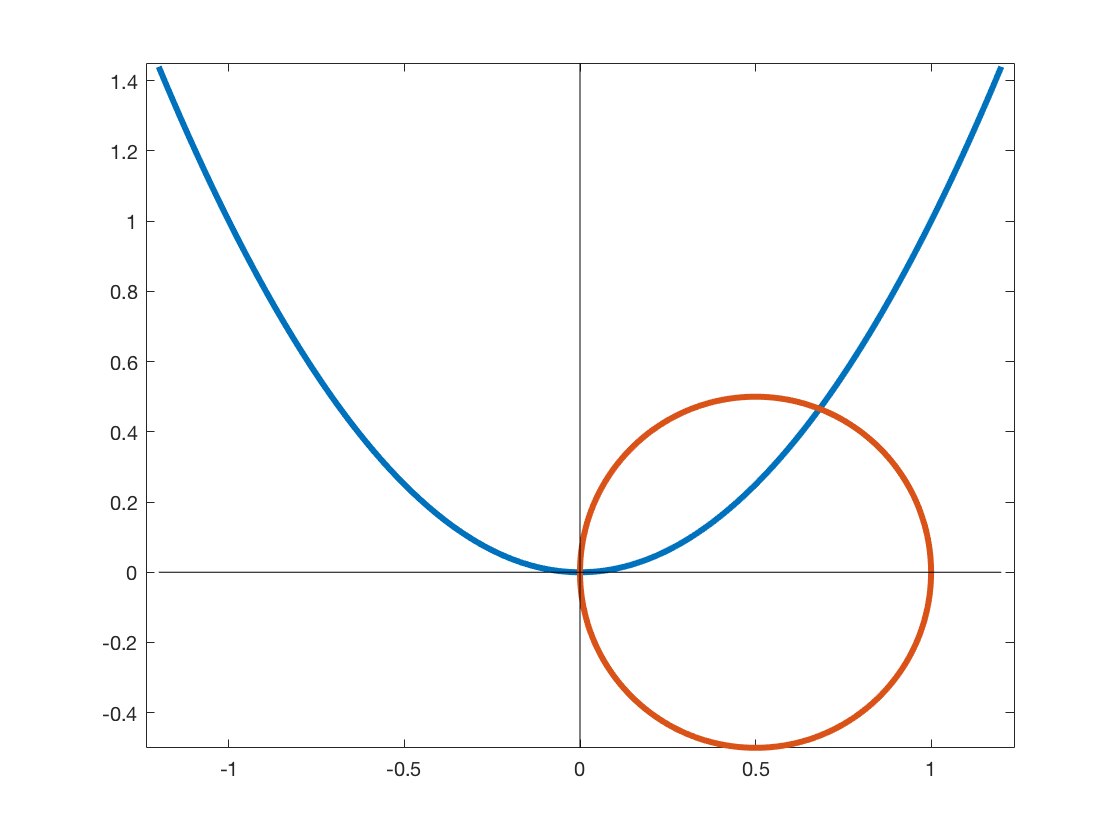

x=linspace(-1.2,1.2,1000);
yparabola=x.^2;
figure
plot(x,yparabola,'linewidth',3);
hold on
theta=linspace(0,2*pi,1000);
r0=1/2;
xcirc=1/2+r0*cos(theta);
ycric=r0*sin(theta);
plot(xcirc,ycric,'linewidth',3)
plot([-1.2 1.2],[0 0],'k-')
plot([0 0],[-0.5 1.45],'k-')

% place your lines here:
%plot ....
%plot ....
axis equal 

**(f) (2 points)** We can also find the intersection of the parabola and the circle by the fzero command:

f1=@(x) x^2;
f2=@(x) f1(x).^2+(x-1/2).^2-(1/2)^2;
xrootnew=fzero(f2,0.2)

xrootnew = 5.0700e-18

xrootnew=fzero(f2,[0.2 1])

xrootnew = 0.6823

Can you explain why the xrootnew=fzero(f2,0.2) answer is different from the xrootnew=fzero(f2,[0.2 1]) answer?

% place your comments here: 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% End of HW 10    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [y Np]=int_leftpoint(N,d)
if d==1
    x=linspace(-3,2,N);
    sum=0;
    Np=0;
    for i=1:N-1
        sum=sum+exp(-x(i)^2);
        Np=Np+1;
    end
    dx=x(2)-x(1);
    y=dx*sum;
end

if d==2
    x=linspace(-3,2,N);
    y=linspace(-3,2,N);
    sum=0;
    Np=0;
    for i=1:N-1
        for j=1:N-1
            sum=sum+exp(-(x(i)^2+y(j)^2));
            Np=Np+1;
        end
    end
    dx=x(2)-x(1);
    dy=y(2)-y(1);
    y=dx*dy*sum;
end

if d==3
    x=linspace(-3,2,N);
    y=linspace(-3,2,N);
    z=linspace(-3,2,N);
    sum=0;
    Np=0;
    for i=1:N-1
        for j=1:N-1
            for k=1:N-1
                sum=sum+exp(-(x(i)^2+y(j)^2+z(k)^2));
                Np=Np+1;
            end
        end
    end
    dx=x(2)-x(1);
    dy=y(2)-y(1);
    dz=z(2)-z(1);
    y=dx*dy*dz*sum;
end

if d==4
    x=linspace(-3,2,N);
    y=linspace(-3,2,N);
    z=linspace(-3,2,N);
    w=linspace(-3,2,N);
    sum=0;
    Np=0;
    for i=1:N-1
        for j=1:N-1
            for k=1:N-1
                for l=1:N-1
                    sum=sum+exp(-(x(i)^2+y(j)^2+z(k)^2+w(l)^2));
                    Np=Np+1;
                end
            end
        end
    end
    dx=x(2)-x(1);
    dy=y(2)-y(1);
    dz=z(2)-z(1);
    dw=w(2)-w(1);
    y=dx*dy*dz*dw*sum;
end
end

function NACA=getNACA()
NACA= ...
    [0 0;
    0.0034482758620689659 0.012746937348072772;
    0.0068965517241379318 0.017827955646005946;
    0.010344827586206898 0.02164259759750595;
    0.013793103448275864 0.024798792129209629;
    0.017241379310344827 0.02753204687633512;
    0.020689655172413796 0.029963169346806998;
    0.024137931034482762 0.032163945306212638;
    0.027586206896551727 0.034181164676734516;
    0.031034482758620689 0.036047343098177073;
    0.034482758620689655 0.037786168487987049;
    0.037931034482758627 0.039415535369973581;
    0.041379310344827593 0.040949356906234177;
    0.044827586206896551 0.042398707431044041;
    0.048275862068965524 0.043772575076580292;
    0.051724137931034482 0.04507837575108313;
    0.055172413793103454 0.046322314915682783;
    0.05862068965517242 0.047509648869317571;
    0.062068965517241378 0.048644877688766117;
    0.065517241379310351 0.049731890481057014;
    0.068965517241379309 0.0507740766086709;
    0.072413793103448282 0.05177441215096628;
    0.075862068965517254 0.052735528024682378;
    0.079310344827586213 0.0536597643058121;
    0.082758620689655185 0.054549214022655765;
    0.086206896551724144 0.055405758811789496;
    0.0896551724137931 0.056231098211937974;
    0.093103448275862075 0.057026773930530877;
    0.096551724137931047 0.057794190098874085;
    0.1 0.058534630297799387;
    0.105 0.059562735800195374;
    0.15210526315789474 0.067079453245019849;
    0.19921052631578948 0.071662052834359211;
    0.24631578947368421 0.074144454064793;
    0.29342105263157897 0.0750098875648548;
    0.34052631578947368 0.074579247086754369;
    0.38763157894736838 0.073083859772690746;
    0.43473684210526314 0.070699089240371618;
    0.4818421052631579 0.067561816154093873;
    0.52894736842105261 0.063780349456279736;
    0.57605263157894737 0.059440426058585107;
    0.62315789473684213 0.054609035014893684;
    0.67026315789473678 0.049336959045512205;
    0.71736842105263154 0.043660523040265874;
    0.76447368421052631 0.037602832507652874;
    0.81157894736842107 0.031174672828960664;
    0.85868421052631583 0.024375176392515845;
    0.90578947368421048 0.017192326891248826;
    0.95289473684210524 0.0096033468775866618;
    1 0.0015749999999999723;
    0.95289473684210524 -0.0096033468775866618;
    0.90578947368421048 -0.017192326891248826;
    0.85868421052631583 -0.024375176392515845;
    0.81157894736842107 -0.031174672828960664;
    0.76447368421052631 -0.037602832507652874;
    0.71736842105263154 -0.043660523040265874;
    0.67026315789473678 -0.049336959045512205;
    0.62315789473684213 -0.054609035014893684;
    0.57605263157894737 -0.059440426058585107;
    0.52894736842105261 -0.063780349456279736;
    0.4818421052631579 -0.067561816154093873;
    0.43473684210526314 -0.070699089240371618;
    0.38763157894736838 -0.073083859772690746;
    0.34052631578947368 -0.074579247086754369;
    0.29342105263157897 -0.0750098875648548;
    0.24631578947368421 -0.074144454064793;
    0.19921052631578948 -0.071662052834359211;
    0.15210526315789474 -0.067079453245019849;
    0.105 -0.059562735800195374;
    0.1 -0.058534630297799387;
    0.096551724137931047 -0.057794190098874085;
    0.093103448275862075 -0.057026773930530877;
    0.0896551724137931 -0.056231098211937974;
    0.086206896551724144 -0.055405758811789496;
    0.082758620689655185 -0.054549214022655765;
    0.079310344827586213 -0.0536597643058121;
    0.075862068965517254 -0.052735528024682378;
    0.072413793103448282 -0.05177441215096628;
    0.068965517241379309 -0.0507740766086709;
    0.065517241379310351 -0.049731890481057014;
    0.062068965517241378 -0.048644877688766117;
    0.05862068965517242 -0.047509648869317571;
    0.055172413793103454 -0.046322314915682783;
    0.051724137931034482 -0.04507837575108313;
    0.048275862068965524 -0.043772575076580292;
    0.044827586206896551 -0.042398707431044041;
    0.041379310344827593 -0.040949356906234177;
    0.037931034482758627 -0.039415535369973581;
    0.034482758620689655 -0.037786168487987049;
    0.031034482758620689 -0.036047343098177073;
    0.027586206896551727 -0.034181164676734516;
    0.024137931034482762 -0.032163945306212638;
    0.020689655172413796 -0.029963169346806998;
    0.017241379310344827 -0.02753204687633512;
    0.013793103448275864 -0.024798792129209629;
    0.010344827586206898 -0.02164259759750595;
    0.0068965517241379318 -0.017827955646005946;
    0.0034482758620689659 -0.012746937348072772;
    0 -0];
end

function trout=gettrout()
trout = ...
    [0 0;
    0.0034482758620689659 0.011703906444120643;
    0.0068965517241379318 0.01649455048129456;
    0.010344827586206898 0.020131471607500617;
    0.013793103448275864 0.02316482521120072;
    0.017241379310344827 0.025808505768979945;
    0.020689655172413796 0.028172602266589471;
    0.024137931034482762 0.03032274085400688;
    0.027586206896551727 0.032301828025868513;
    0.031034482758620689 0.034139768624199665;
    0.034482758620689655 0.035858410130741057;
    0.037931034482758627 0.03747430133419815;
    0.041379310344827593 0.039000342208259035;
    0.044827586206896551 0.040446825749759094;
    0.048275862068965524 0.0418221252879184;
    0.051724137931034482 0.043133164548454853;
    0.055172413793103454 0.044385749006076905;
    0.05862068965517242 0.045584805546358666;
    0.062068965517241378 0.04673455969700125;
    0.065517241379310351 0.047838669248339766;
    0.068965517241379309 0.048900326720172534;
    0.072413793103448282 0.049922339130264684;
    0.075862068965517254 0.050907190932583606;
    0.079310344827586213 0.051857094279081833;
    0.082758620689655185 0.052774029597977459;
    0.086206896551724144 0.053659778679791874;
    0.0896551724137931 0.054515951898867036;
    0.093103448275862075 0.055344010795533041;
    0.096551724137931047 0.05614528695229544;
    0.1 0.056920997883030837;
    0.105 0.058002629250750351;
    0.15210526315789474 0.066136933721190269;
    0.19921052631578948 0.071483283459231536;
    0.24631578947368421 0.0748110135635184;
    0.29342105263157897 0.076548436464052738;
    0.34052631578947368 0.076966689238716454;
    0.38763157894736838 0.076252196338340072;
    0.43473684210526314 0.074540774220769254;
    0.4818421052631579 0.071935702482061686;
    0.52894736842105261 0.068518155047217241;
    0.57605263157894737 0.0643536259590542;
    0.62315789473684213 0.059496095794459462;
    0.67026315789473678 0.053990847440813242;
    0.71736842105263154 0.047876435394091463;
    0.76447368421052631 0.041186103299190258;
    0.81157894736842107 0.033948829705069093;
    0.85868421052631583 0.026190116081204931;
    0.90578947368421048 0.017932591702454339;
    0.95289473684210524 0.0091964855781628413;
    1 0;
    0.95289473684210524 -0.0091964855781628413;
    0.90578947368421048 -0.017932591702454339;
    0.85868421052631583 -0.026190116081204931;
    0.81157894736842107 -0.033948829705069093;
    0.76447368421052631 -0.041186103299190258;
    0.71736842105263154 -0.047876435394091463;
    0.67026315789473678 -0.053990847440813242;
    0.62315789473684213 -0.059496095794459462;
    0.57605263157894737 -0.0643536259590542;
    0.52894736842105261 -0.068518155047217241;
    0.4818421052631579 -0.071935702482061686;
    0.43473684210526314 -0.074540774220769254;
    0.38763157894736838 -0.076252196338340072;
    0.34052631578947368 -0.076966689238716454;
    0.29342105263157897 -0.076548436464052738;
    0.24631578947368421 -0.0748110135635184;
    0.19921052631578948 -0.071483283459231536;
    0.15210526315789474 -0.066136933721190269;
    0.105 -0.058002629250750351;
    0.1 -0.056920997883030837;
    0.096551724137931047 -0.05614528695229544;
    0.093103448275862075 -0.055344010795533041;
    0.0896551724137931 -0.054515951898867036;
    0.086206896551724144 -0.053659778679791874;
    0.082758620689655185 -0.052774029597977459;
    0.079310344827586213 -0.051857094279081833;
    0.075862068965517254 -0.050907190932583606;
    0.072413793103448282 -0.049922339130264684;
    0.068965517241379309 -0.048900326720172534;
    0.065517241379310351 -0.047838669248339766;
    0.062068965517241378 -0.04673455969700125;
    0.05862068965517242 -0.045584805546358666;
    0.055172413793103454 -0.044385749006076905;
    0.051724137931034482 -0.043133164548454853;
    0.048275862068965524 -0.0418221252879184;
    0.044827586206896551 -0.040446825749759094;
    0.041379310344827593 -0.039000342208259035;
    0.037931034482758627 -0.03747430133419815;
    0.034482758620689655 -0.035858410130741057;
    0.031034482758620689 -0.034139768624199665;
    0.027586206896551727 -0.032301828025868513;
    0.024137931034482762 -0.03032274085400688;
    0.020689655172413796 -0.028172602266589471;
    0.017241379310344827 -0.025808505768979945;
    0.013793103448275864 -0.02316482521120072;
    0.010344827586206898 -0.020131471607500617;
    0.0068965517241379318 -0.01649455048129456;
    0.0034482758620689659 -0.011703906444120643;
    0 -0];
end
